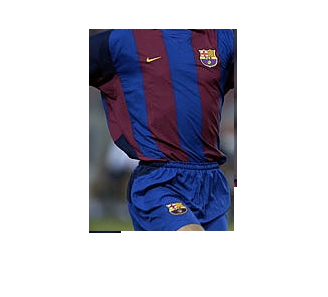

clear
%imPrueba = imread('..\acmilan\01.jpg');
imPrueba = imread('22.jpg');
imshow(imPrueba)

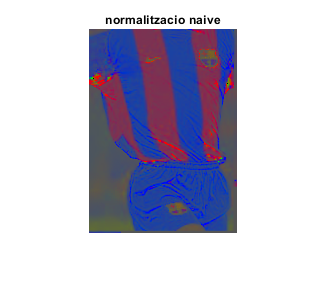

rTest = imPrueba(:,:,1);
gTest = imPrueba(:,:,2);
bTest = imPrueba(:,:,3);
ITest = double(rTest)+double(gTest)+double(bTest);
rTestn = double(rTest)./ITest;
gTestn = double(gTest)./ITest;
bTestn = double(bTest)./ITest;
rgbTestNormalizada = cat(3,rTestn,gTestn,bTestn);
%rgbTestNormalizada = cat(3,rTestn,zeros(size(rTestn)),bTestn);
imshow(rgbTestNormalizada), title('normalitzacio naive');

%%Normalizacion
rHistEq = histeq(rTestn);

bHistEq = histeq(bTestn);

gHistEq = histeq(gTestn);

rgbTestNormalizada = cat(3,rHistEq,gHistEq,bHistEq);
%imshow(rgbTestNormalizada), title('Histograma Equalizado')

n = 1

n = 1

[h, w, d] = size(rgbTestNormalizada)

h = 204

w = 148

d = 3

hAux = fix(h/n)

hAux = 204

wAux = fix(w/n)

wAux = 148

hAux2 = h-(hAux*(n-1))

hAux2 = 204

wAux2 = w-(wAux*(n-1))

wAux2 = 148

chiR = 30192

chiG = 30192

chiB = 30192

a1 = ones(1,n);
a2 = ones(1,n);
for i = 1:(n-1)
    a1(i) = hAux;
    a2(i) = wAux;
end
a1(n) = hAux2;
a2(n) = wAux2;
mat16 = mat2cell(rgbTestNormalizada,a1,a2, [d]);
aux = 0:0.01:1;
%imshow(mat16{1,1});
for i = 1:n
    for j = 1:n
        subImagen = mat16{i,j};
        rTest = subImagen(:,:,1);
        gTest = subImagen(:,:,2);
        bTest = subImagen(:,:,3);
        %rHistEq = histeq(rTest);
        %bHistEq = histeq(gTest);
        %gHistEq = histeq(bTest);
        %bar(rHistEq)
        %bar(bHistEq)
        %bar(gHistEq)
        rTest = uint8(rTest * 256);
        gTest = uint8(gTest * 256);
        bTest = uint8(bTest * 256);
        rTestHisto = getHisto(rTest);
        gTestHisto = getHisto(gTest);
        bTestHisto = getHisto(bTest);
        %Empezamos comprobacion imagen
        for i = 22:22
            if i < 10
                im = imread(strcat('0', int2str(i) ,'.jpg'));
            else
                im = imread(strcat( int2str(i) ,'.jpg'));
            end
            imshow(im)
            r = im(:,:,1);
            g = im(:,:,2);
            b = im(:,:,3);
            I = double(r)+double(g)+double(b);
            rn = double(r)./I;
            gn = double(g)./I;
            bn = double(b)./I;
            rgbNormalizada = cat(3,rn,gn,bn);
            imshow(rgbNormalizada), title('normalitzacio naive')
            %%Equalizacion
            rHistEq = histeq(rn);
            gHistEq = histeq(gn);
            bHistEq = histeq(bn);
            r = uint8(rHistEq * 256);
            g = uint8(gHistEq * 256);
            b = uint8(bHistEq * 256);
            rHisto = getHisto(r);
            gHisto = getHisto(g);
            bHisto = getHisto(b);
            chiR = distChi(rHisto,rTestHisto)
            chiG = distChi(gHisto,gTestHisto)
            chiB = distChi(bHisto,bTestHisto)
        end
    end
end


auxTest = 0:0.001:1;
%aux = 0:256
histogram(rgbTestNormalizada(:,:,1),auxTest), title('histograma_red');
histogram(rgbTestNormalizada(:,:,3),auxTest), title('histograma_blue');

%Algoritmo
%length_blue = zeros(1,30);
%length_red = zeros(1,30);
for i = 1:40
    if i < 10
        im = imread(strcat('0', int2str(i) ,'.jpg'));
    else
        im = imread(strcat( int2str(i) ,'.jpg'));
    end
    imshow(im)
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    I = double(r)+double(g)+double(b);
    rn = double(r)./I;
    gn = double(g)./I;
    bn = double(b)./I;
    rgbNormalizada = cat(3,rn,gn,bn);
    imshow(rgbNormalizada), title('normalitzacio naive')
    %%Normalizacion
    rgbNormalizada = histeq(rgbNormalizada);
    imshow(rgbNormalizada), title('Histograma Equalizado')
    aux = 0:0.001:1;
    %aux = 0:256
    histogram(rgbNormalizada(:,:,1),aux), title('histograma_red');
    histogram(rgbNormalizada(:,:,3),aux), title('histograma_blue');
    %length_red(i) =  length(rn(rn>0.7));
    %length_blue(i)= length(bn(bn>0.7));
end



function d = distChi(l1,l2)
    d = sum(((l1-l2).^2)/l1+l2);
end

function h = getHisto(im)
    h = zeros(1,256);
    [files cols] = size(im);
    for f=1:files
        for c=1:cols
            h(im(f,c)+1) = h(im(f,c)+1)+1;
        end
    end
end